DrivFace = load("data/DrivFace/DrivFace.mat"); % http://archive.ics.uci.edu/ml/datasets/DrivFace

DFdata = DrivFace.drivFaceD.data;

TCGA = csvread("data/TCGA-PANCAN-HiSeq-801x20531/data.csv", 1, 1); % http://archive.ics.uci.edu/ml/machine-learning-databases/00401/
TCGA = TCGA(:,1:5000); % Take a subset due to processor melting

ds = [1,2,4,8,16,32,64,128,256,512];
es_pca_df = zeros(10,1);
es_pca_gram_df = zeros(10,1);
es_pca_matlab_df = zeros(10,1);

es_pca_tc = zeros(10,1);
es_pca_gram_tc = zeros(10,1);
es_pca_matlab_tc = zeros(10,1);

times_pca_df = zeros(10,1);
times_pca_gram_df = zeros(10,1);
times_pca_matlab_df = zeros(10,1);

times_pca_tc = zeros(10,1);
times_pca_gram_tc = zeros(10,1);
times_pca_matlab_tc = zeros(10,1);


dfc = center(DFdata);
tcc = center(TCGA);

Running the algorithms and metrics.

for i = 1:10
    ds(i)
    [~, e_pca_df, t_pca_df] = pca_vanilla(DFdata, dfc, ds(i), true);
    [~, e_pca_gram_df, t_pca_gram_df] = pca_gram(DFdata, dfc, ds(i), true);
    
    tic;
    pca_matlab_df = pca(DFdata);
    e_pca_matlab_df = reconstruction_error(DFdata, pca_matlab_df(:,1:ds(i)));
    t_pca_matlab_df = toc;
    
    es_pca_df(i) = e_pca_df;
    es_pca_gram_df(i) = e_pca_gram_df;
    es_pca_matlab_df(i) = e_pca_matlab_df;
    times_pca_df(i) = t_pca_df;
    times_pca_gram_df(i) = t_pca_gram_df;
    times_pca_matlab_df(i) = t_pca_matlab_df;
    
    [~, e_pca_tc, t_pca_tc] = pca_vanilla(TCGA, tcc, ds(i), true);
    [~, e_pca_gram_tc, t_pca_gram_tc] = pca_gram(TCGA, tcc, ds(i), true);
    
    tic;
    pca_matlab_tc = pca(TCGA);
    e_pca_matlab_tc = reconstruction_error(TCGA, pca_matlab_tc(:,1:ds(i)));
    t_pca_matlab_tc = toc;
    
    es_pca_tc(i) = e_pca_tc;
    es_pca_gram_tc(i) = e_pca_gram_tc;
    es_pca_matlab_tc(i) = e_pca_matlab_tc; 
    times_pca_tc(i) = t_pca_tc;
    times_pca_gram_tc(i) = t_pca_gram_tc;
    times_pca_matlab_tc(i) = t_pca_matlab_tc;
end

ans = 1

ans = 2

ans = 4

ans = 8

ans = 16

ans = 32

ans = 64

ans = 128

ans = 256

ans = 512

Plotting

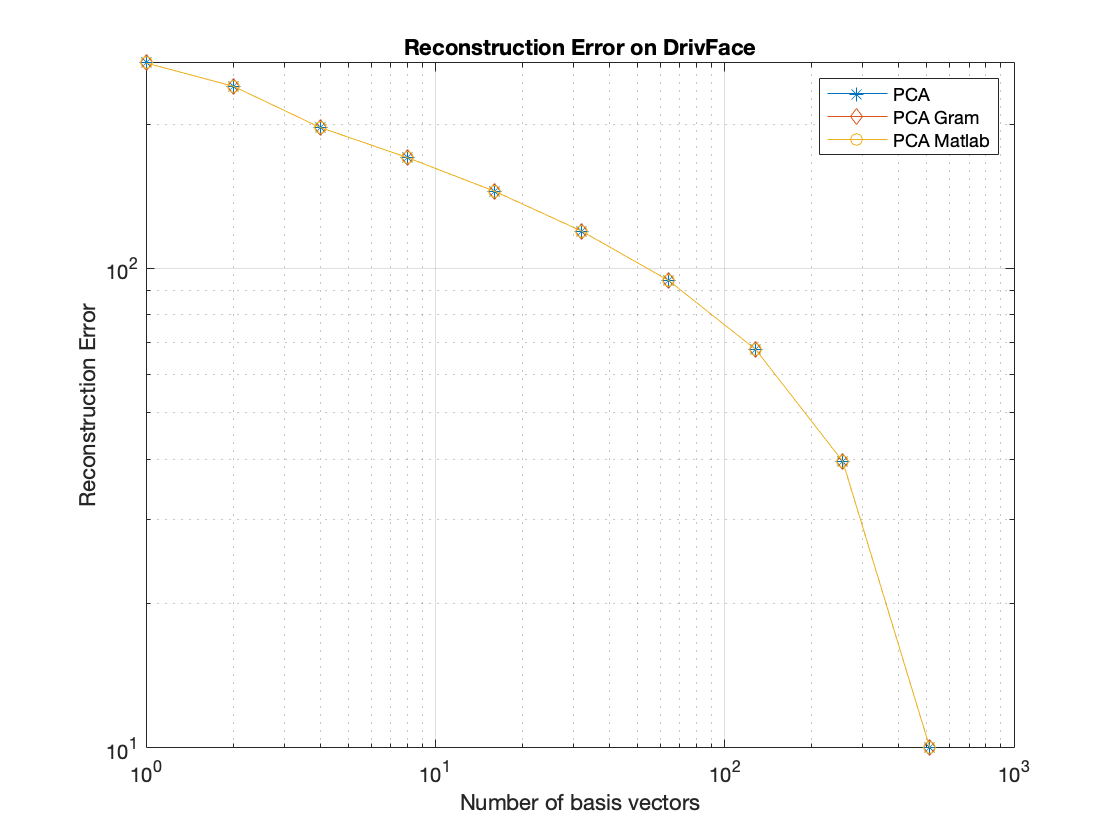

lg = loglog(ds, es_pca_df, ds, es_pca_gram_df, ds, es_pca_matlab_df);
lg(1).Marker = '*';
lg(2).Marker = 'd';
lg(3).Marker = 'o';
grid on
legend('PCA','PCA Gram', 'PCA Matlab', 'Location', 'northeast');
title('Reconstruction Error on DrivFace')
xlabel('Number of basis vectors')
ylabel('Reconstruction Error')

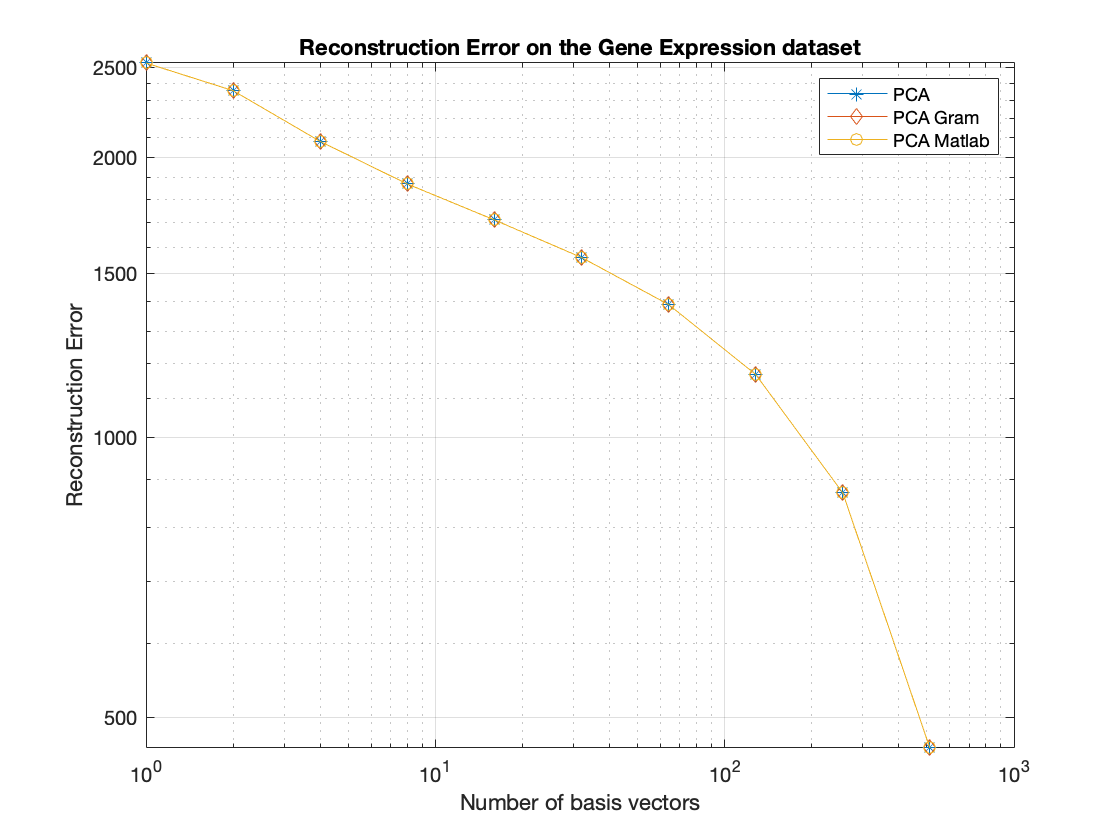


lg = loglog(ds, es_pca_tc, ds, es_pca_gram_tc, ds, es_pca_matlab_tc);
lg(1).Marker = '*';
lg(2).Marker = 'd';
lg(3).Marker = 'o';
grid on
legend('PCA','PCA Gram', 'PCA Matlab', 'Location', 'northeast');
title('Reconstruction Error on the Gene Expression dataset')
xlabel('Number of basis vectors')
ylabel('Reconstruction Error')

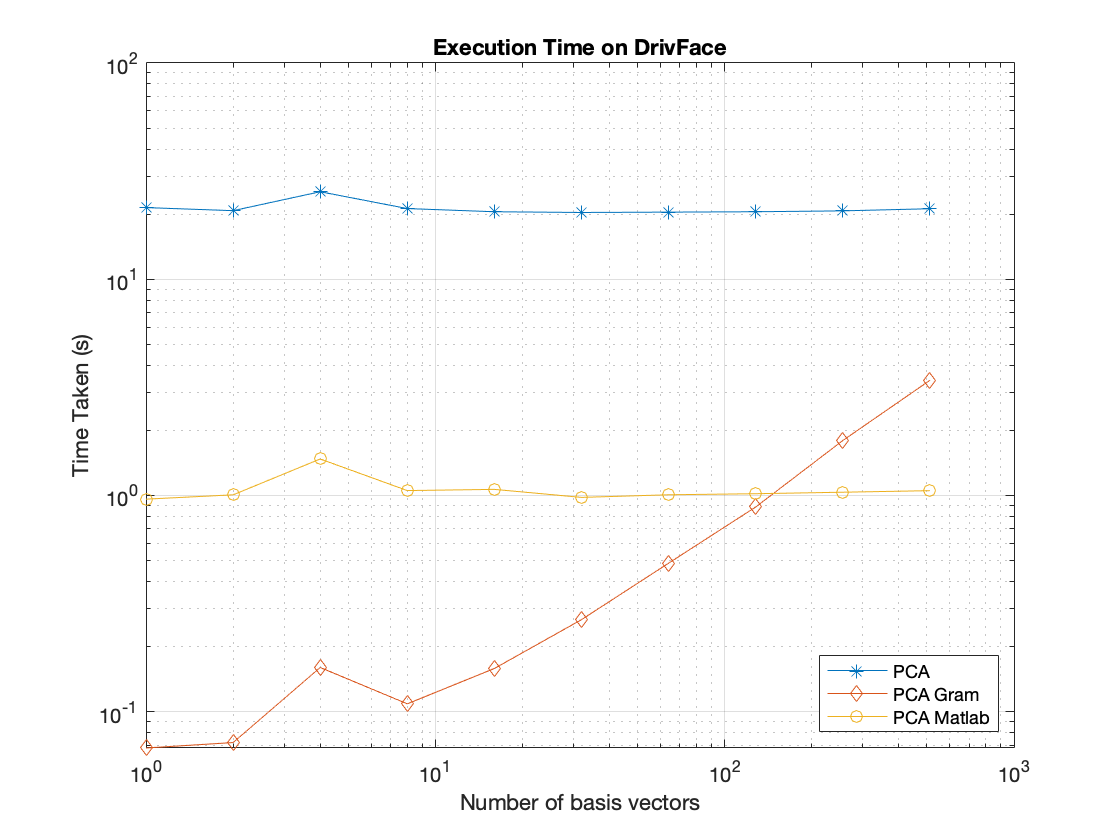


lg = loglog(ds, times_pca_df, ds, times_pca_gram_df, ds, times_pca_matlab_df);
lg(1).Marker = '*';
lg(2).Marker = 'd';
lg(3).Marker = 'o';
grid on
legend('PCA','PCA Gram', 'PCA Matlab', 'Location', 'southeast');
title('Execution Time on DrivFace')
xlabel('Number of basis vectors')
ylabel('Time Taken (s)')

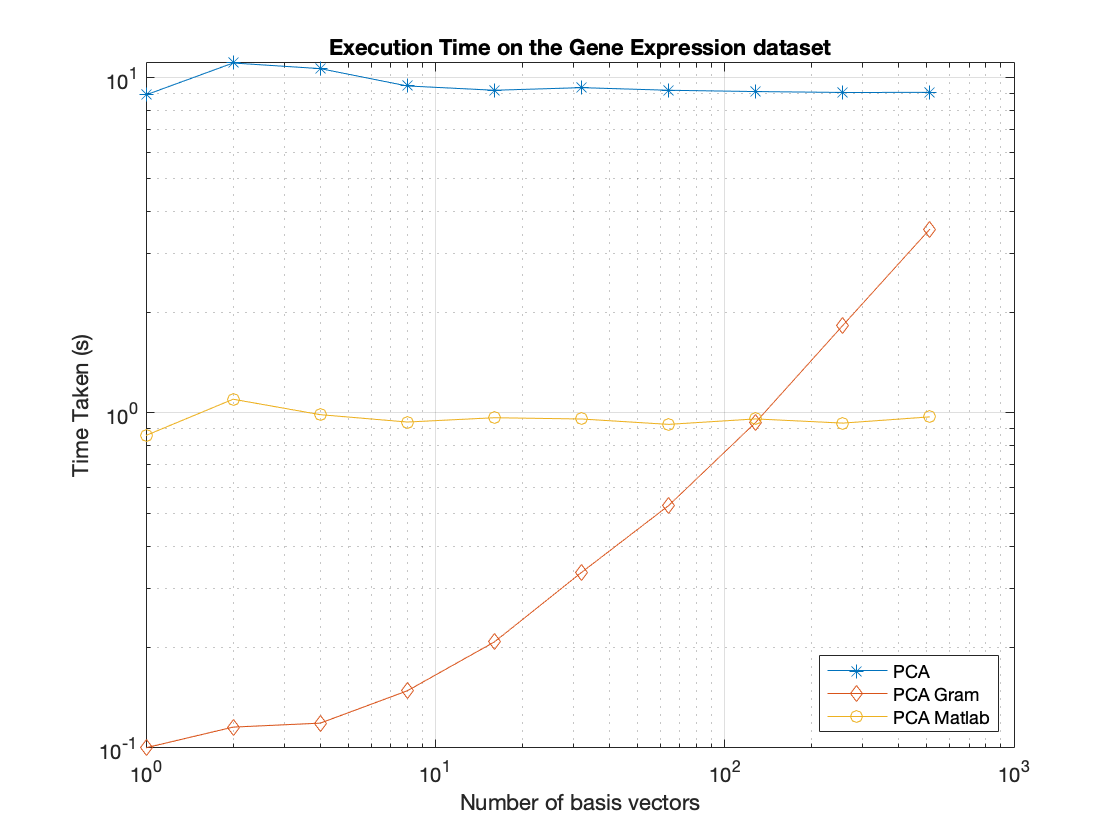


lg = loglog(ds, times_pca_tc, ds, times_pca_gram_tc, ds, times_pca_matlab_tc);
lg(1).Marker = '*';
lg(2).Marker = 'd';
lg(3).Marker = 'o';
grid on
legend('PCA','PCA Gram', 'PCA Matlab', 'Location', 'southeast')
title('Execution Time on the Gene Expression dataset')
xlabel('Number of basis vectors')
ylabel('Time Taken (s)')

Plotting Eigenfaces

[basis_vecs, ~, ~] = pca_gram(DFdata, dfc, ds(i), true);
[basis_vecs_v, ~, ~] = pca_vanilla(DFdata, dfc, ds(i), true);

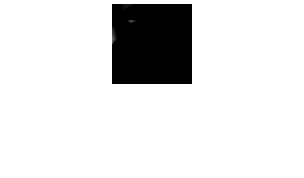

e1 = reshape(basis_vecs(:,1)*100, 80, 80);
e2 = reshape(basis_vecs(:,2)*100, 80, 80);
e3 = reshape(basis_vecs(:,3)*100, 80, 80);
e4 = reshape(basis_vecs(:,4)*100, 80, 80);
imshow(e1)

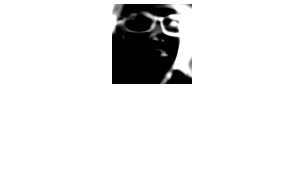

imshow(e2)

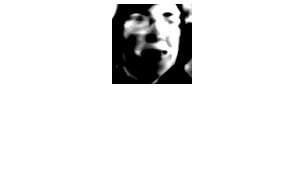

imshow(e3)

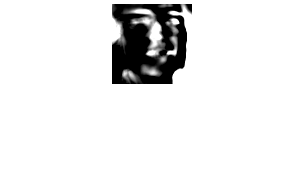

imshow(e4)

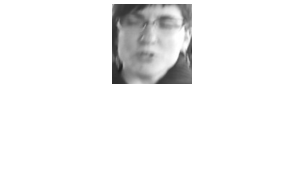

i1 = reshape(DFdata(1,:), 80, 80);
i2 = reshape(DFdata(200,:), 80, 80);
i3 = reshape(DFdata(300,:), 80, 80);
i4 = reshape(DFdata(400,:), 80, 80);
imshow(i1)

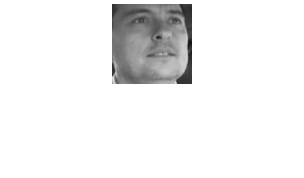

imshow(i2)

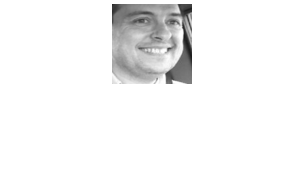

imshow(i3)

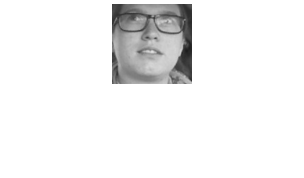

imshow(i4)

Viewing reconstructions of Gram PCA for different amounts of basis vectors.

ds = [606, 512, 128, 32, 8, 1];

imwrite(reshape(DFdata(1, :), 80, 80), "Reconstructions2/1-orig.jpg");
imwrite(reshape(DFdata(101, :), 80, 80), "Reconstructions2/101-orig.jpg");
imwrite(reshape(DFdata(201, :), 80, 80), "Reconstructions2/201-orig.jpg");

for i=1:6
    d = ds(i);
    [basis_vecs, e, t] = pca_gram(DFdata, dfc, d, true);
    reconstruction = DFdata * (basis_vecs * basis_vecs.');
    
    imwrite(reshape(reconstruction(1,:), 80, 80), sprintf("Reconstructions2/1-%d.jpg", d));
    imwrite(reshape(reconstruction(101,:), 80, 80), sprintf("Reconstructions2/101-%d.jpg", d));
    imwrite(reshape(reconstruction(201,:), 80, 80), sprintf("Reconstructions2/201-%d.jpg", d));
end

Methods to calculate PCA and the metrics used.

function [basis_vecs, e, t] = pca_vanilla(m, mc, d, compute_error)
    tic;
    C = cov(mc);
    [V, D] = eig(C);
    [~, ind] = sort(diag(D), 'descend'); % Fetch the top d eigenvalues and indices
    basis_vecs = V(:,ind(1:d)); % Select the top d eigenvectors
    t = toc;
    if compute_error
        e = reconstruction_error(m, basis_vecs);
    end
end

function [basis_vecs, e, t] = pca_gram(m, mc, d, compute_error)
    tic;
    [V, D] = eig(1/(size(mc, 1))*(mc*mc.'));        % Calculate eigenvalues of (1/m)YY^T (we have row data)
    [D_sorted, ind] = sort(diag(D), 'descend');     % Fetch the top d eigenvalues and indices
    eigen_vecs = V(:,ind(1:d));                     % Select the d best eigenvectors
    basis_vecs = zeros(size(mc, 2), d);             % Pre-allocate
    for i = 1:d
        eigenvalue = D_sorted(i);
        eigenvector = eigen_vecs(:,i);
        normed = (eigenvector/norm(eigenvector));
        basis_vec = 1/sqrt(eigenvalue) * mc.' * normed; % Calculate basis vector i
        basis_vecs(:,i) = basis_vec / norm(basis_vec);
    end
    t = toc;
    if compute_error
        e = reconstruction_error(m, basis_vecs); % For some reason the error increases with Gram PCA. No idea what is going on.
    end
end

function e = reconstruction_error(m, basis_vecs)
    mc = center(m);
    MC_res = mc * (basis_vecs * basis_vecs.');
    error_mat = norm(mc - MC_res, 'fro');
    e = sum(error_mat);
end

function mc = center(m)
    m_mean = mean(m, 1);                            
    mc = m;
    for i=1:size(m,1)
        mc(i,:) = mc(i,:) - m_mean;
    end
end